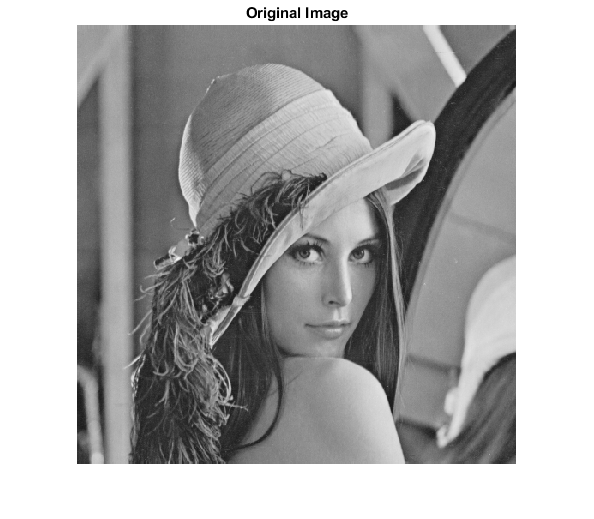

% Q1a
I = im2uint8(rgb2gray(imread('lena_std.tif')));
imshow(I), title("Original Image");


% Q1b
[row, col] = size(I);
cnt_pixels = row * col;
disp("The size of the image is: " + cnt_pixels);

The size of the image is: 262144



% Q1c
max_val = max(I(:));
disp("The maximum pixel value is: " + max_val);

The maximum pixel value is: 245



% Q1d
mean_val = mean(I(:));
disp("The mean pixel value is: " + mean_val);

The mean pixel value is: 124.0425


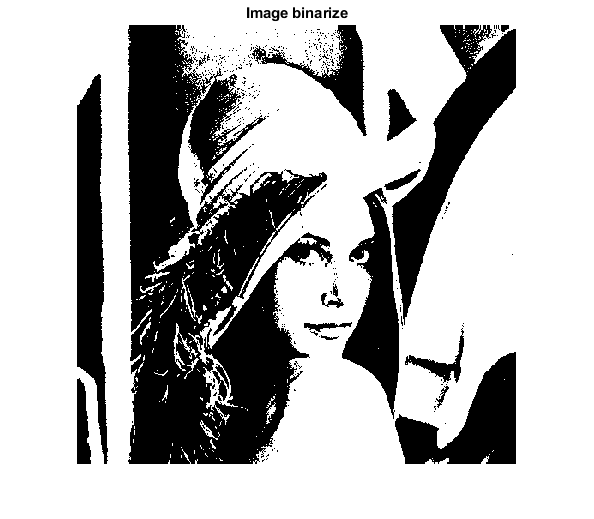


% Q1e
bw = I;
for c = 1:col
    for r = 1:row
        if bw(r,c) >= mean_val
            bw(r,c) = 1;
        else
            bw(r,c) = 0;
        end
    end
end
imshow(bw,[0 1]), title("Image binarize");

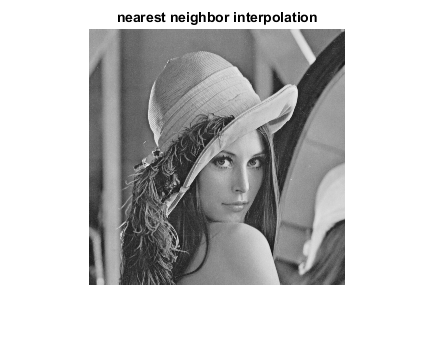


% Q2

factor = 0.5;

% nearest neighbor interpolation
nn = imresize(I,[row*factor,col*factor],'nearest');
imshow(nn), title("nearest neighbor interpolation");

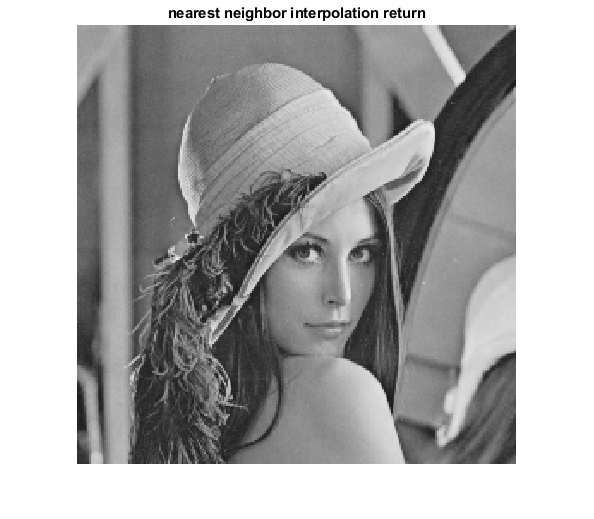

nn_aft = imresize(nn,[row,col],'nearest');
imshow(nn_aft), title("nearest neighbor interpolation return");

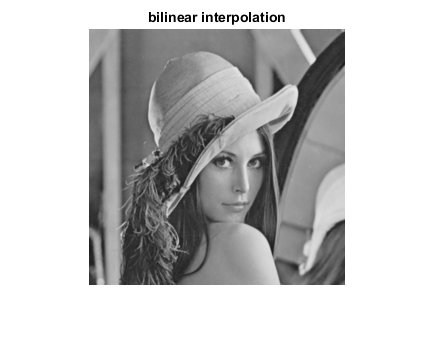


% bilinear interpolation
bl = imresize(I,[row*factor,col*factor],'bilinear');
imshow(bl), title("bilinear interpolation");

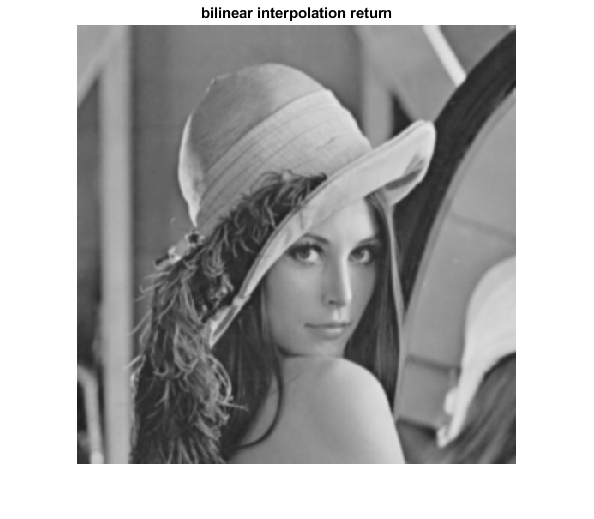

bl_aft = imresize(bl,[row,col],'bilinear');
imshow(bl_aft), title("bilinear interpolation return");

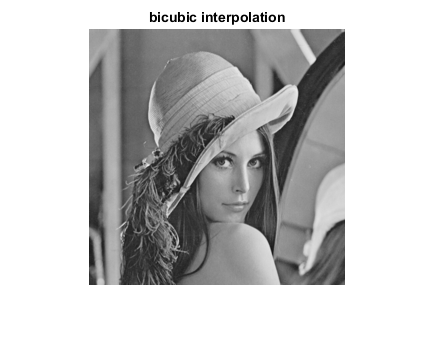


% bicubic interpolation
bc = imresize(I,[row*factor,col*factor],'bicubic');
imshow(bc), title("bicubic interpolation");

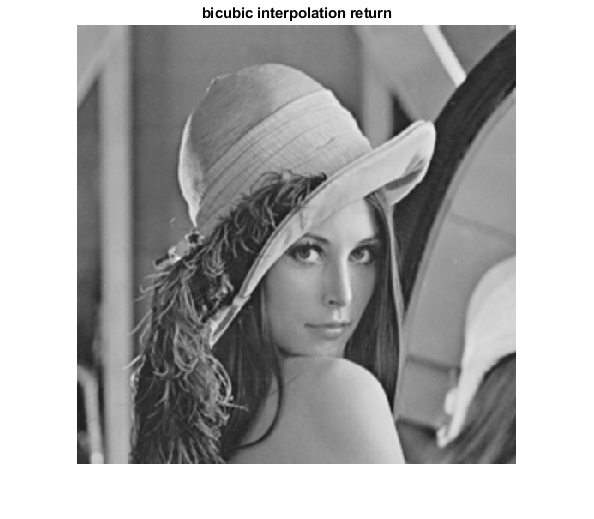

bc_aft = imresize(bc,[row,col],'bicubic');
imshow(bc_aft), title("bicubic interpolation return");

% personalized factor
factor = input("Input resize factor: ");

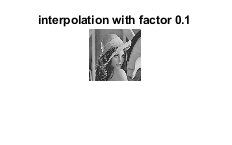

nn = imresize(I,[row*factor,col*factor],'nearest');
imshow(nn), title("interpolation with factor "+factor);

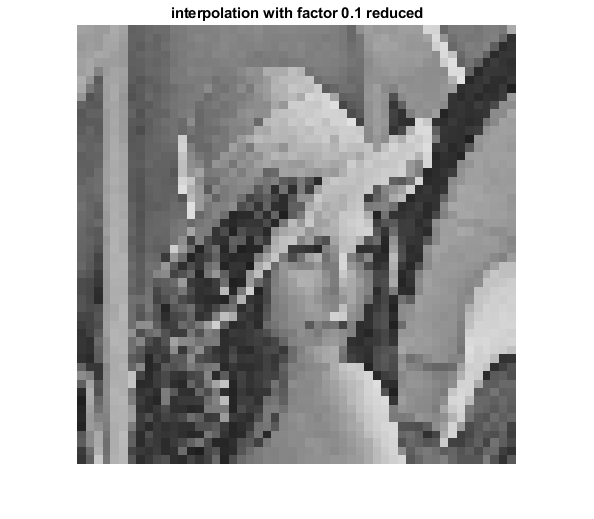

nn_aft = imresize(nn,[row,col],'nearest');
imshow(nn_aft), title("interpolation with factor "+factor+" reduced");

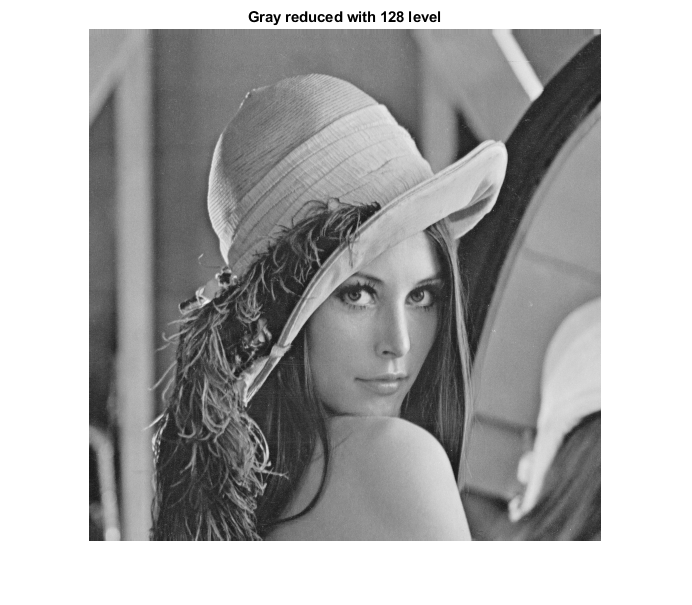


% Q3
red_dict = [256,128,64,32,16,8,4,2];
for i=1:length(red_dict)
    redu = I*((red_dict(i)-1)/255);
    imshow(redu,[0 red_dict(i)-1]), title("Gray reduced with "+red_dict(i)+" level");
    drawnow;
    pause(0.5);
end

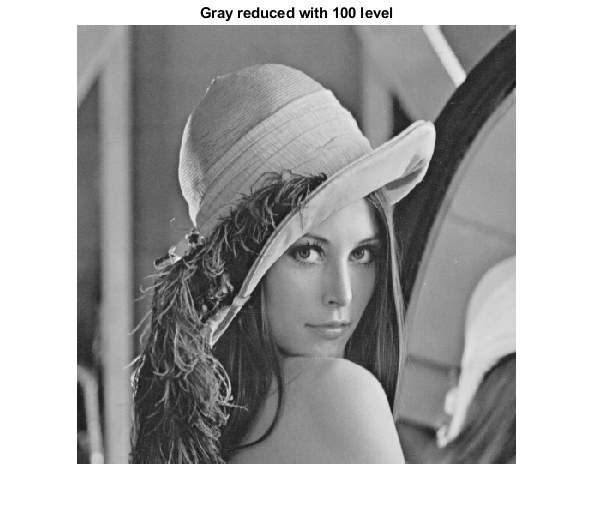


ngray_lev = input("Input gray reduce factor: ");
redu = I*((ngray_lev-1)/255);
imshow(redu,[0 ngray_lev-1]), title("Gray reduced with "+ngray_lev+" level");